clear
P1 = [500 0 500];
P2 = [700 500 400];
P3 = [700 500 600];
P_vec ={P1,P2,P3};

1.1 

n = 10; %grid dense
Full_Sol_Mat = [];
UniqeFlag = true; 
for idx = 1:3
    fprintf('For desired  position P%d:',idx)
    disp(P_vec{idx})
    fprintf('The solutions are:')
    [SolMat, ~] = Serach_For_IK(Get_IG_mat(n),P_vec{idx},UniqeFlag) ;% calculate the all solutions with the function 'Grid_Serach_For_IK'
    disp(SolMat)
    Full_Sol_Mat.(['P',num2str(idx)]) = SolMat; % add the current solutios to the final solutions matrixs
end

For desired  position P1:

   500     0   500



The solutions are:

    3.1416    4.2766    6.2305
    3.1416    5.7111    3.3912
    6.2832    0.1807    0.4991
    6.2832    2.1782    2.8394



For desired  position P2:

   700   500   400



The solutions are:

    0.6202    1.1972    5.3722
    0.6202    1.7635    4.2495



For desired  position P3:

   700   500   600



The solutions are:

No solution found!


1.2

% initilaize while conditions
Min_Num_flag = false;
UniqeFlag = true;
Number_possible_solution = [length(Full_Sol_Mat.P1(:,1)) ,length(Full_Sol_Mat.P2(:,1)) , length(Full_Sol_Mat.P3(:,1))];

min_n = 20; % intitialze n to the maximum density
while ~Min_Num_flag 
    min_n = min_n-1;
    for idx = 1:3
        [~, SolNum] = Serach_For_IK(Get_IG_mat(min_n),P_vec{idx},UniqeFlag); % calculate the number of possible solitions with the current n
        if  Number_possible_solution(idx) > SolNum
            Min_Num_flag = true; % Flag that rise when the solution number decrease.
            break
        end % end if , decrease is solutions
     end % end for, idx 
end % end while

No solution found!
No solution found!
No solution found!
No solution found!
No solution found!
No solution found!
No solution found!
No solution found!
No solution found!
No solution found!
No solution found!
No solution found!
No solution found!
No solution found!
No solution found!
No solution found!
No solution found!


min_n = min_n+1;
fprintf('The minimum number of iteration is %d',min_n)

The minimum number of iteration is 3

1.3

UniqeFlag = true;

for idx = 1:3
    RandGuess = 2*pi*rand(min_n,3); % initial guesses splited randomly
    fprintf('For desired  position P%d:',idx)
    disp(P_vec{idx})
    fprintf('The solutions are:')
    [SolMat, ~] = Serach_For_IK(RandGuess,P_vec{idx},UniqeFlag);
    disp(SolMat)
end

For desired  position P1:

   500     0   500



The solutions are:

    6.2832    0.1807    0.4991
    6.2832    2.1782    2.8394



For desired  position P2:

   700   500   400



The solutions are:

    0.6202    1.1972    5.3722
    0.6202    1.7635    4.2495



For desired  position P3:

   700   500   600



The solutions are:

No solution found!


1.4

% building a solution cloud
Sol_cloud = [];
UniqeFlag = false;
RandGuess = 2*pi*rand(min_n,3);
for idx = 1:3
    Sol_cloud.RndGeuss.IG = RandGuess; % remmember all the initial guesses
    [SolMat, ~] = Serach_For_IK(Sol_cloud.RndGeuss.IG,P_vec{idx},UniqeFlag); % get the complete solution matrix
    Sol_cloud.RndGeuss.(['P',num2str(idx)]) = SolMat; % save the sloution matrix eith the 'no solution' rows
    
    % do for minimum density grid and maximum density grid
    Sol_cloud.MinN.IG = Get_IG_mat(min_n);
    [SolMat, ~] = Serach_For_IK(Sol_cloud.MinN.IG,P_vec{idx},UniqeFlag);
    Sol_cloud.MinN.(['P',num2str(idx)]) = SolMat;
    
    Sol_cloud.MaxN.IG = Get_IG_mat(20);
    [SolMat, ~] = Serach_For_IK(Sol_cloud.MaxN.IG,P_vec{idx},UniqeFlag);
    Sol_cloud.MaxN.(['P',num2str(idx)]) = SolMat;
    
end

No solution found!


No solution found!


No solution found!


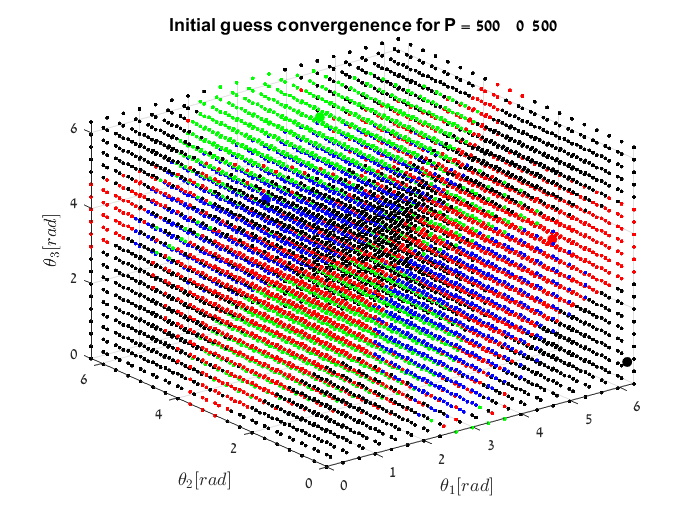

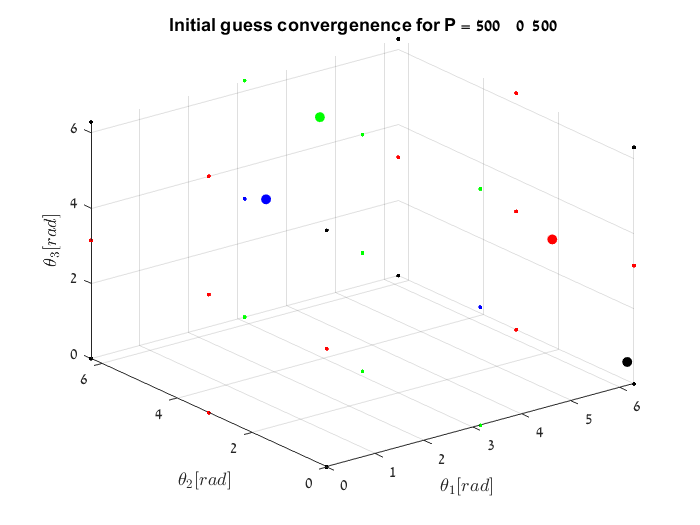

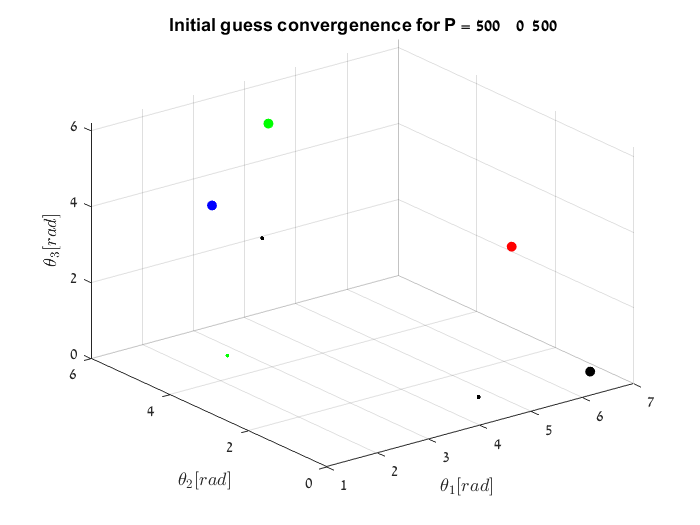

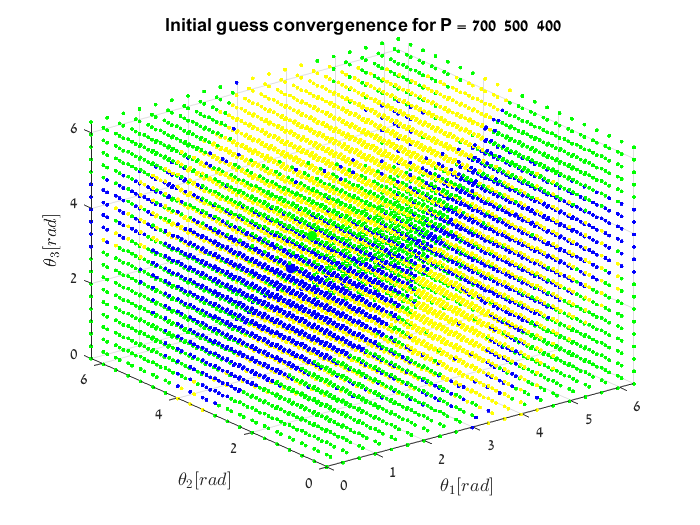

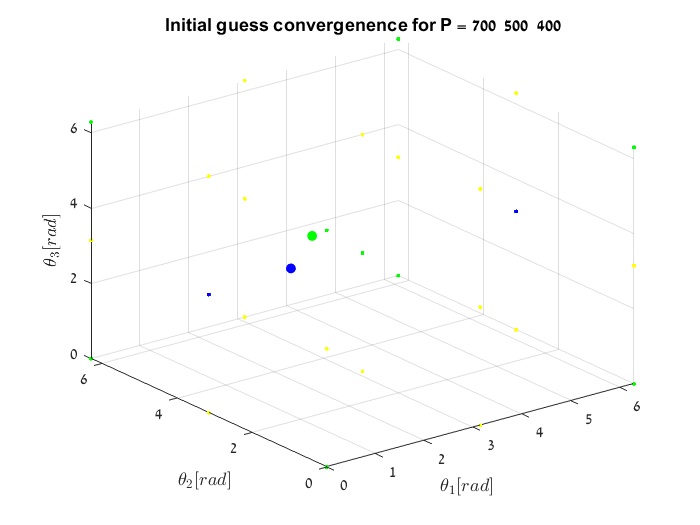

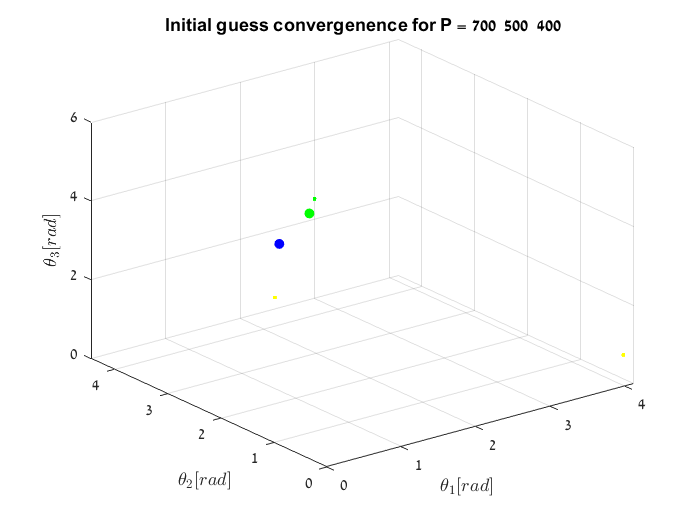

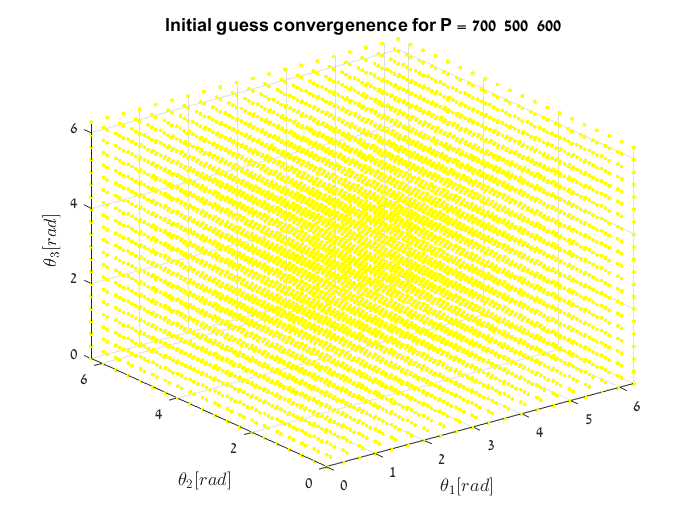

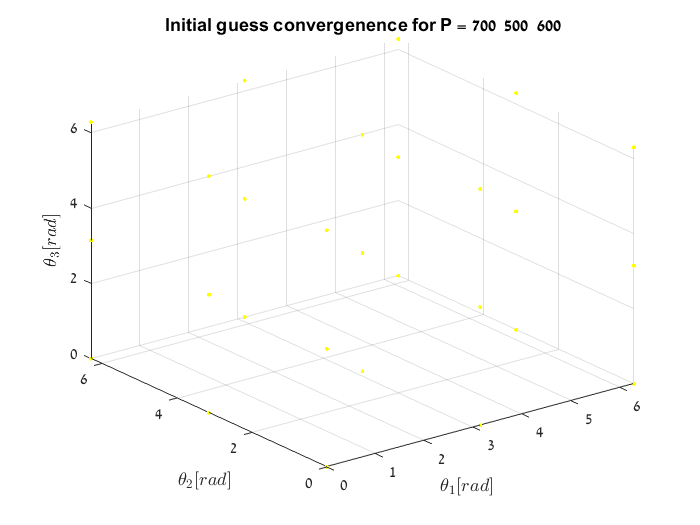

Final_Sol_Color = [0 1 0;0 0 1;0 0 0;1 0 0]; % set the color for the solutions

for idx = 1:3
    Pi_Sol_Mat = Full_Sol_Mat.(['P',num2str(idx)]); % get the final solution matrix for P_i
    Sol_C = Final_Sol_Color(1:length(Pi_Sol_Mat(:,1)),:); % update the solution colors
    
    figure
    X = Sol_cloud.MaxN.IG(:,1);
    Y = Sol_cloud.MaxN.IG(:,2);
    Z = Sol_cloud.MaxN.IG(:,3);
    [~,ib] = ismembertol(Sol_cloud.MaxN.(['P',num2str(idx)]),Pi_Sol_Mat,1e-2,'ByRows',true); % replace the solution in the solution matrix with the row nuber of the final solution matrix
    C = repmat([1 1 0],numel(X),1); % initilaize C to yellow and replace later the color base on the solution number
    C(ib==1,:) = ones(length(C(ib==1)),1)*[0 1 0];
    C(ib==2,:) = ones(length(C(ib==2)),1)*[0 0 1];
    C(ib==3,:) = ones(length(C(ib==3)),1)*[0 0 0];
    C(ib==4,:) = ones(length(C(ib==4)),1)*[1 0 0];
    scatter3(X,Y,Z,[],C,'Marker','.')
   
    xlabel('$\theta_1 [rad]$','Interpreter',"latex")
    ylabel('$\theta_2 [rad]$','Interpreter',"latex")
    zlabel('$\theta_3 [rad]$','Interpreter',"latex")
    title(['Initial guess convergenence for P = ',num2str(P_vec{idx})])
    hold on
    scatter3(Pi_Sol_Mat(:,1),Pi_Sol_Mat(:,2),Pi_Sol_Mat(:,3),[],Sol_C,'filled','Marker','o')
    hold off
    
    % same as above 
    figure
    X = Sol_cloud.MinN.IG(:,1);
    Y = Sol_cloud.MinN.IG(:,2);
    Z = Sol_cloud.MinN.IG(:,3);
    [~,ib] = ismembertol(Sol_cloud.MinN.(['P',num2str(idx)]),Pi_Sol_Mat,1e-2,'ByRows',true);
    C = repmat([1 1 0],numel(X),1);
    C(ib==1,:) = ones(length(C(ib==1)),1)*[0 1 0];
    C(ib==2,:) = ones(length(C(ib==2)),1)*[0 0 1];
    C(ib==3,:) = ones(length(C(ib==3)),1)*[0 0 0];
    C(ib==4,:) = ones(length(C(ib==4)),1)*[1 0 0];
    scatter3(X,Y,Z,[],C,'Marker','.')
    xlabel('$\theta_1 [rad]$','Interpreter',"latex")
    ylabel('$\theta_2 [rad]$','Interpreter',"latex")
    zlabel('$\theta_3 [rad]$','Interpreter',"latex")
    title(['Initial guess convergenence for P = ',num2str(P_vec{idx})])
    hold on
    scatter3(Pi_Sol_Mat(:,1),Pi_Sol_Mat(:,2),Pi_Sol_Mat(:,3),[],Sol_C,'filled','Marker','o')
    hold off
    
    figure
    X = Sol_cloud.RndGeuss.IG(:,1);
    Y = Sol_cloud.RndGeuss.IG(:,2);
    Z = Sol_cloud.RndGeuss.IG(:,3);
    [~,ib] = ismembertol(Sol_cloud.RndGeuss.(['P',num2str(idx)]),Pi_Sol_Mat,1e-2,'ByRows',true);
    C = repmat([1 1 0],numel(X),1);
    C(ib==1,:) = ones(length(C(ib==1)),1)*[0 1 0];
    C(ib==2,:) = ones(length(C(ib==2)),1)*[0 0 1];
    C(ib==3,:) = ones(length(C(ib==3)),1)*[0 0 0];
    C(ib==4,:) = ones(length(C(ib==4)),1)*[1 0 0];
    scatter3(X,Y,Z,[],C,'Marker','.')
    xlabel('$\theta_1 [rad]$','Interpreter',"latex")
    ylabel('$\theta_2 [rad]$','Interpreter',"latex")
    zlabel('$\theta_3 [rad]$','Interpreter',"latex")
    title(['Initial guess convergenence for P = ',num2str(P_vec{idx})])
    hold on
    scatter3(Pi_Sol_Mat(:,1),Pi_Sol_Mat(:,2),Pi_Sol_Mat(:,3),[],Sol_C,'filled','Marker','o')
    hold off
    
end